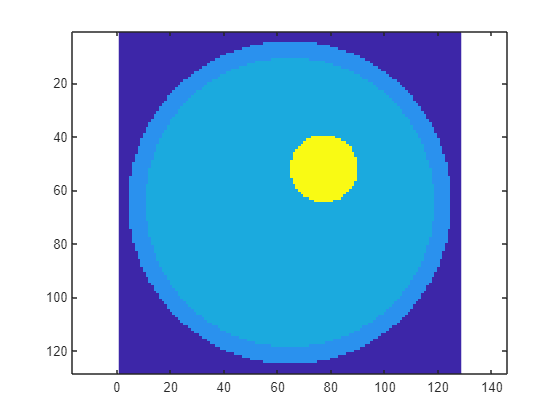

% Written by KhaiNguyen

imagesc(IMG50)
title('Original Image')
colormap(parula), axis('equal') 

% plot images of PSF on subplot
% compare filters

% How choice of projection angles & choice of filter affect image quality
% USE imagec(log10(abs(IMG)), [-10,0]
IMG = zeros(N,N);
IMG(N/4,N/4) = 1; % single non-zero point. Location doesn't matter

% ----- for loop -----
theta = [0:179]; % 180 projection angles ---- theta = # of projection angles
[p,r] = radon(IMG,theta);  % radon func add just number of pixels at each angle (diag = side*sqrt(2))



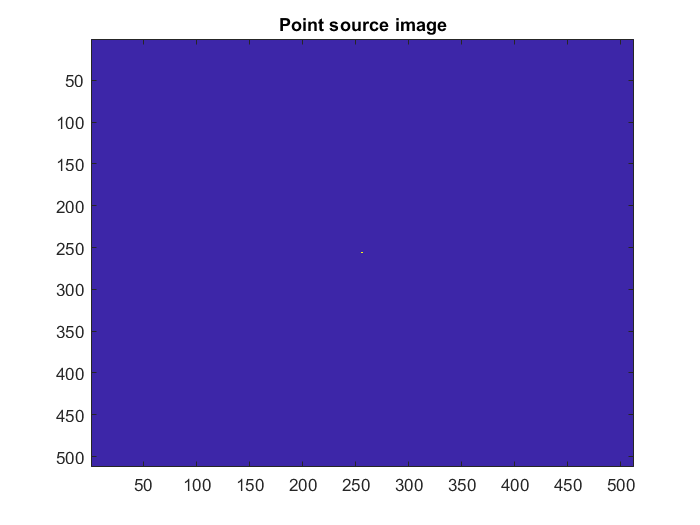

close all
N = 512;
IMGp = zeros(N,N);
IMGp((N)/2,(N)/2) = 1;
imagesc(IMGp)
title("Point source image")

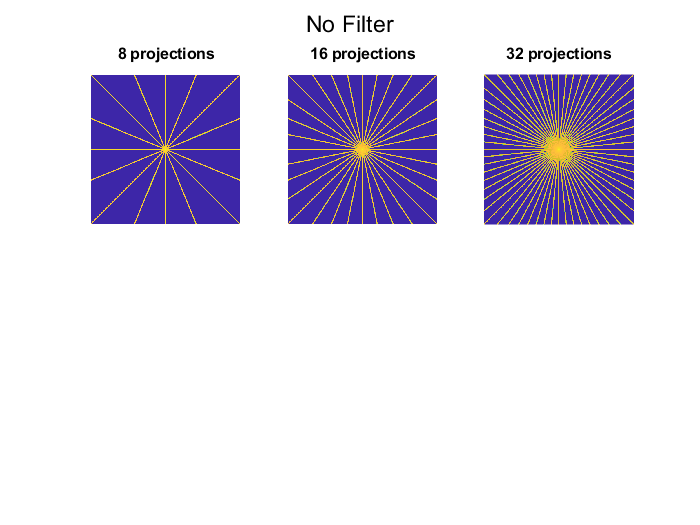

num_angles = [8, 16, 32]; %, 64, 128, 256];
% ------------------ NO FILTER -------------------
% figure
% for k = 1:length(num_angles)
%     subplot(2,3,k)
%     for Np = 1:1:num_angles(k)
%         kp = [0:180/Np:179];
%         [p,r] = radon(IMGp,kp);
%         hb = iradon(p,kp,'linear','none'); % no filter
%         h = surf(hb);
%         set(h,'LineStyle','none','FaceColor','interp');
%         
%         title([int2str(Np),' projections'])
%         if Np <32
%             pause(0.5)
%         else
%             pause(.1)
%         end
%         
%     end
% end

% ---------- point source image --------------
figure
sgtitle("No Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','none'); % no filter
        imagesc(log10(abs(hb)),[-10,0]); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

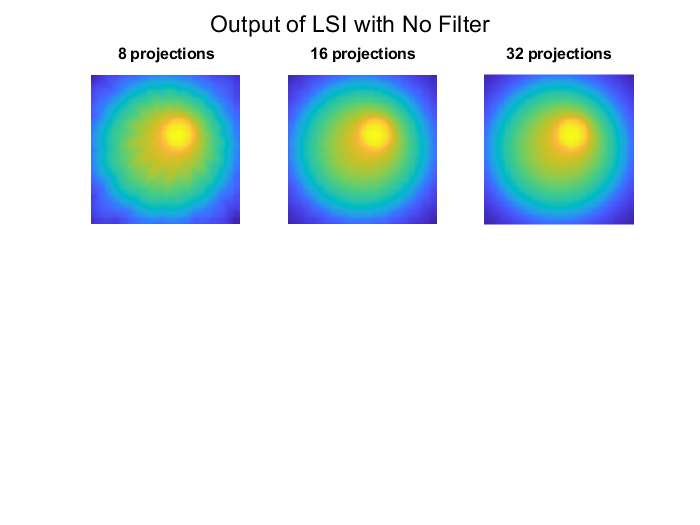


% ----------------- apply on original image ---------------
figure
sgtitle("Output of LSI with No Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','none'); % no filter
        IMG_LSI = conv2(IMG50,hb,'same');
        imagesc(IMG_LSI); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

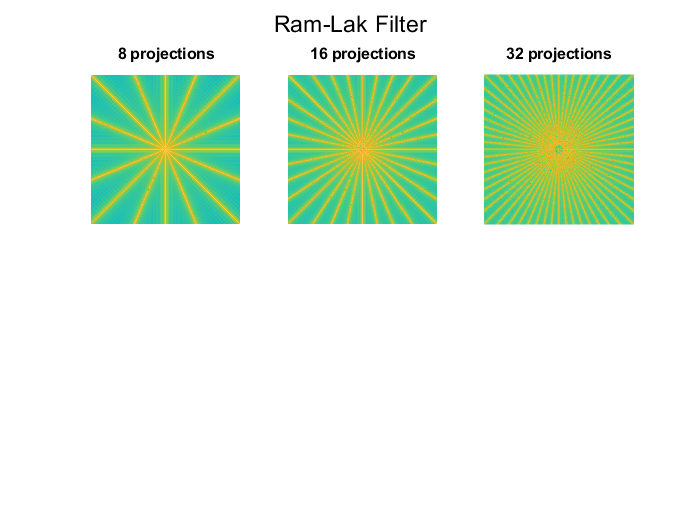

% ------------------ Ram-Lak FILTER -------------------
figure
sgtitle("Ram-Lak Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Ram-Lak'); % Ram-Lak filter
        imagesc(log10(abs(hb)),[-10,0]); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

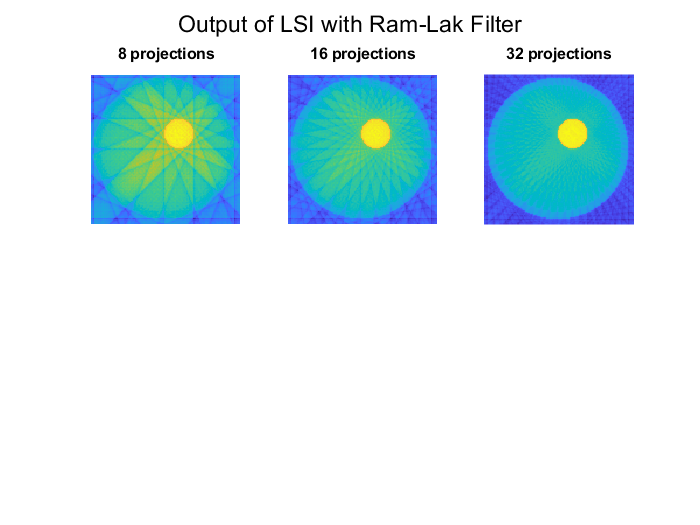


% ----------------- apply on original image ---------------
figure
sgtitle("Output of LSI with Ram-Lak Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Ram-Lak'); % Ram-Lak filter
        IMG_LSI = conv2(IMG50,hb,'same');
        imagesc(IMG_LSI); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

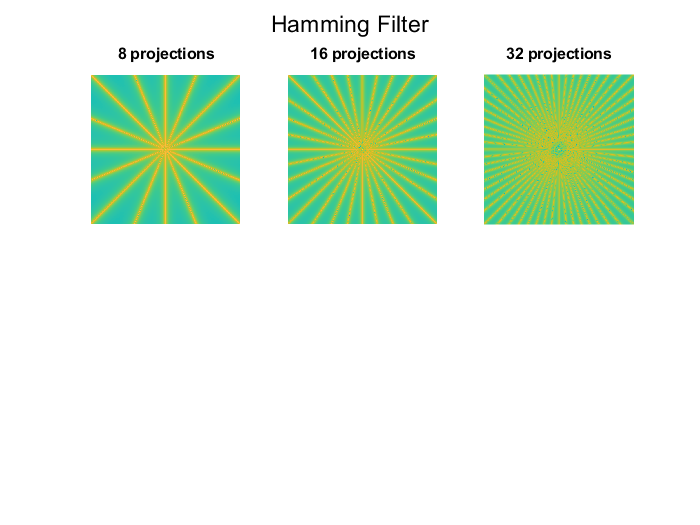

% ------------------ Hamming FILTER -------------------
figure
sgtitle("Hamming Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Hamming'); % Hamming filter
        imagesc(log10(abs(hb)),[-10,0]); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

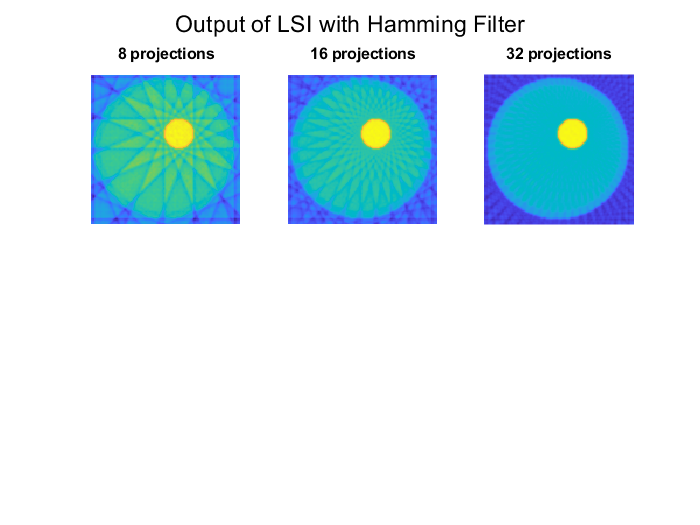

% ----------------- apply on original image ---------------
figure
sgtitle("Output of LSI with Hamming Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Hamming'); % Hamming filter
        IMG_LSI = conv2(IMG50,hb,'same');
        imagesc(IMG_LSI); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end